## Example of spanning

Example in 2 dimensions

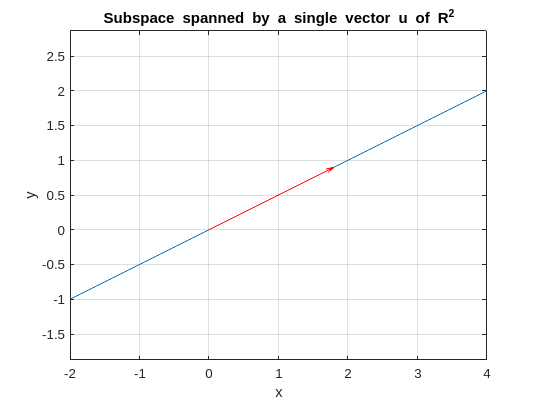

u=[2 1]'; syms a real; W=a*u;
ezplot(W(1),W(2),[-1 2])
title("Subspace spanned by a single vector u of R^2"); hold on; axis equal;  grid on
quiver(0,0,u(1),u(2),'r');

clf;

Example in 3 dimensions

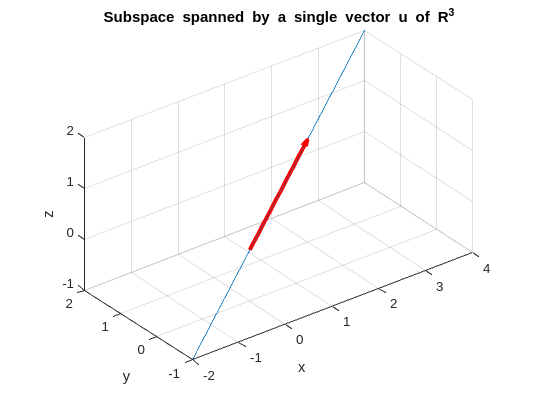


u=[2 1 1]'; syms a real; W=a*u;
ezplot3(W(1),W(2),W(3), [-1 2]); figure(2); hold on; 
title("Subspace spanned by a single vector u of R^3");
axis equal
quiver3(0,0,0, u(1),u(2),u(3),1,'Color','r','LineWidth',3)

clf;

Example with a matrix

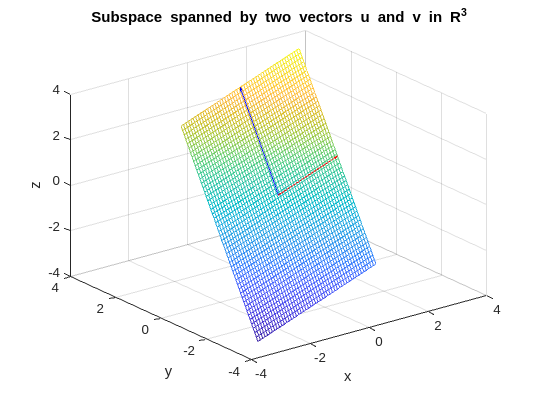

u=[1 3 3]'; v=[2 0 1]';
syms a b real; W=a*u + b*v;
ezmesh(W(1),W(2),W(3), [-1 1])
hold on; title("Subspace spanned by two vectors u and v in R^3")
quiver3(0,0,0,u(1),u(2),u(3),0,'Color','b');
quiver3(0,0,0,v(1),v(2),v(3),0,'Color','r');

clf;

## Parametric equation of a line

Segment code

P1=[1 1]';
P2=[3 2]';
syms lambda real
P=P1+lambda*(P2-P1);
ezplot(P(1),P(2),[-1 3]); axis([0 6 0 4]);
hold on; grid on; box on; axis equal;

Verify that the following pointers lies on the line:

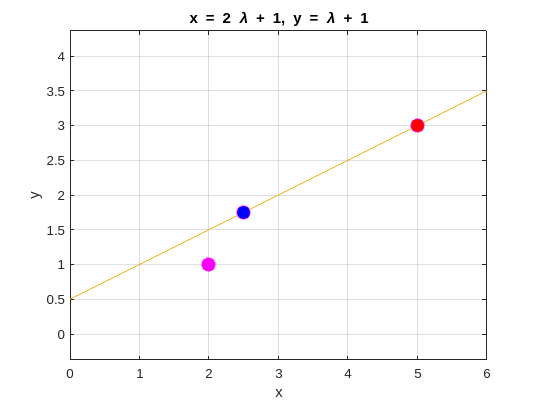

P3=[2 1]'; P4=[5 3]'; P5=[2.5 1.75]';
plot(P3(1),P3(2),'om','MarkerSize',10,'MarkerFaceColor','m'); %Doesn't lie
plot(P4(1),P4(2),'om','MarkerSize',10,'MarkerFaceColor','r'); %Lie on the line
plot(P5(1),P5(2),'om','MarkerSize',10,'MarkerFaceColor','b');

Using solve to verify if they lies or not:

%solve(Equation, variable). We solve with respect to lambda
s = solve(P-P4==0,lambda) %Returns 2 

$$s = 2$$

s = solve(P-P3==0,lambda) %Returns "empty sym"

 
s =
 
Empty sym: 0-by-1
 
